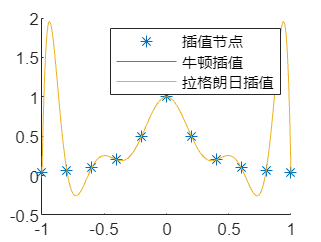

clc; clear; close all;

% f: 定义目标函数 f(x) = 1/(1+25*x^2)
f = @(x) 1./(1+25*x.^2);

% x: 插值节点的 x 坐标 (从 -1 到 1，每 0.2 为一个间隔)
x = -1:0.2:1;     

% y: 插值节点的 y 坐标，对应 x 处函数 f(x) 的值
y = f(x);

% xx: 插值点的 x 坐标 (从 -1 到 1，每 0.01 为一个间隔，用于绘制插值曲线)
xx = -1:0.01:1;

% yy1: 牛顿插值法计算的在 xx 处的插值结果
yy1 = newton_interpolation(x, y, xx);

% yy2: 拉格朗日插值法计算的在 xx 处的插值结果
yy2 = lagrange_interpolation(x, y, xx);

% 绘制插值结果的图形
figure
hold on  
plot(x, y, '*', 'DisplayName', '插值节点')  
plot(xx, yy1, 'DisplayName', '牛顿插值')   
plot(xx, yy2, 'DisplayName', '拉格朗日插值') 
legend  